**Problem 1- Standard Distribution.**

**A) Standard-Normal Distribution**

Starting with the Equation for a Gaussian Distribution

$P\left(x\right)=\frac{1}{\sigma \sqrt{2\pi }}e^{-\frac{{\left(x-\mu \right)}^2 }{2\sigma^2 }}$  (**Eq. 1)**

Where,

$\mu$ = Mean (Center of the Gaussian Distribution), and

$\sigma \;$= Standard Deviation ( Spread of the Distribution).

In a Standard Distribution,

$z=\frac{\left(x-\mu \right)}{\sigma }$,      $\;\;\;\;\;\;\;\textrm{dz}=\frac{\textrm{dx}}{\sigma }$,

$\mu =0$, and                $\sigma =1$.

Yielding,

$P\left(x\right)\textrm{dx}=\frac{1}{\sqrt{2\pi }}e^{-\frac{z^2 }{2}} \textrm{dz}$   (**Eq. 2)**

for the Probability density equation.

mu=0;
sigma=1

sigma = 1


x=linspace(-15,15,201);
z=(x-mu)/sigma

z =   -15.0000  -14.8500  -14.7000  -14.5500  -14.4000  -14.2500  -14.1000  -13.9500  -13.8000  -13.6500  -13.5000  -13.3500  -13.2000  -13.0500  -12.9000  -12.7500  -12.6000  -12.4500  -12.3000  -12.1500  -12.0000  -11.8500  -11.7000  -11.5500  -11.4000  -11.2500  -11.1000  -10.9500  -10.8000  -10.6500  -10.5000  -10.3500  -10.2000  -10.0500   -9.9000   -9.7500   -9.6000   -9.4500   -9.3000   -9.1500   -9.0000   -8.8500   -8.7000   -8.5500   -8.4000   -8.2500   -8.1000   -7.9500   -7.8000   -7.6500


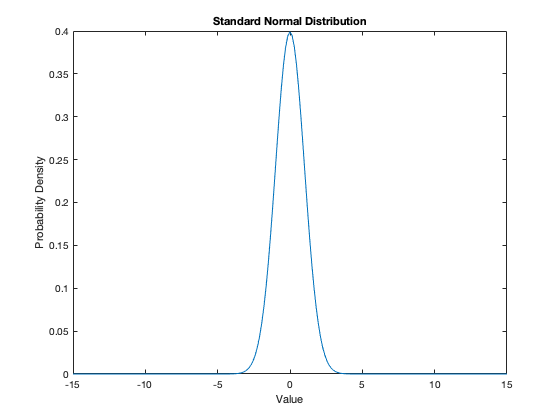


P_density=(1/(sigma*sqrt(2*pi))*exp(-(z).^2/(2)));
figure(35)
plot(x,P_density)
title('Standard Normal Distribution')
ylabel('Probability Density')
xlabel('Value')

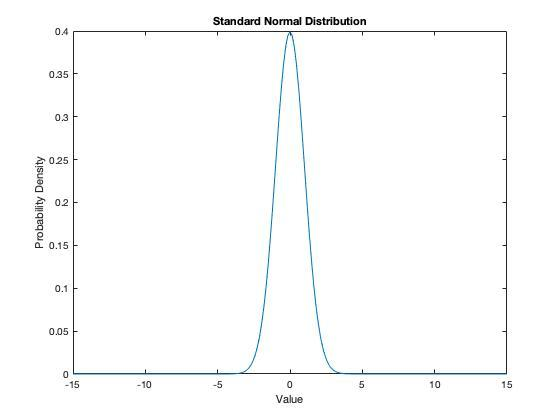

**B) Integrating Normal Distribution.**

To find the probability a particular measurement will land between two possible  values on a Standard-Normal Distribution we use the "normcdf" function of matlab. This function works by integrating the probability density for the Normal Distribution from a boundary value to infinity. This sum is then subtracted from 1 to get the probability desired. 

$\textrm{normcdf}\left(x\right)=\frac{1}{2}\textrm{erfc}\left(-\frac{x}{\sqrt{2}}\right)$       **(Eq. 3)**

where $\textrm{erfc}\left(x\right)=1-\textrm{erf}\left(x\right)=\frac{2}{\sqrt{\pi }}\int_x^{\infty } e^{-z^2 } \textrm{dz}$.  **(Eq. 4)**

We can see that the erfc is just the probability density for a Normal-Distribution with the bounds of integration swapped and adjusted for the positive and negative tails not near the mean.

 Below, P outputs a certain probability that corresponds to a Standard-Normal Distribution, given a certain number of Standard Deviations (SD). Here we are integrating the probabilty density equation on on interval equal to the width of three SDs. This area corresponds to a 99.87% chance that a random measurement will fall within three standard deviations of the mean on a normally distributed dataset.

SD=[1; 2; 3];
mu=0;
sigma=1;
P=normcdf(SD,mu,sigma)

P =     0.8413
    0.9772
    0.9987


T= table(SD,P)

T = 3×2 table
    SD       P   
    __    _______

    1     0.84134
    2     0.97725
    3     0.99865


Here **mu **represents the mean and **sigma** represents the spread of the standard-normal distribution. X represents the interval being integrated over, measured in standard deviations.

The code above generates this table of probabilities for 1, 2, and 3 standard deviations. 

These can be compared to the table of Z-scores on Wiki, [https://en.wikipedia.org/wiki/Standard_normal_table.](https://en.wikipedia.org/wiki/Standard_normal_table.)

**C) The Inverse**

To find the Standard Deviation from the probability a value will land in a certain interval, given a Standard-Normal Distribution, we use the "norminv" MATLAB function. To further prove the correctness of both the forward and inverse of z-score/probability calculation I will use the probabilities gathered from the previous problem to generate the original Standard Deviations used: 1,2, and 3.

SD=norminv(P,mu,sigma)

**D) The Minus Sign**

One can see when a probability that is less than half of the distribution is chosen to calculate the inverse, a negative number for SD appears.

**Ex) **

SD=norminv(.46017,mu,sigma)


$$\;\;\;\textrm{SD}=-0\ldotp 01$$


This occurs because of how the limits of integration are chosen. This is easiest to see from the forward problem. Where we are essentially finding the area of the tails, rather than the area centered on the meanm, and subtracting it from 1. This negative SD represents the probability difference between it's positive counterpart probability and 1.

**Problem 2- Lognormal**

figure(2)
d = random('Lognormal', 1., .25, [1,100000]);
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3)
xlim([0,10])

figure(11)
histogram(d,50,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
x = linspace(.8,8,1000);
pd = makedist("Lognormal","mu",1.,"sigma",.25);
plot(x,pdf(pd,x),"LineWidth",2);
set(gca,'YScale','log')
xlim([0,10])


**3- Hypothetical Statistical Analysis**

**A) Hypothetical Value**

5 is the hypothetical experimental value that will be analyzed.

**B) Question**

Is 5 an outlier? Here an outlier will be defined as equal to or more than 3 standard deviations away from the mean.

**C)**